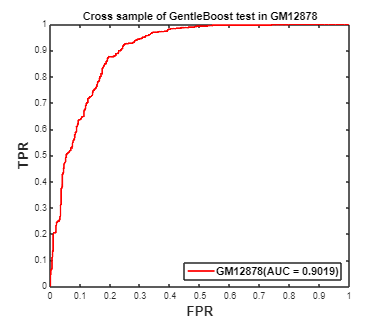

anycell = "K562";  % 只更改细胞名称
openfile = sprintf("trainingWindowIntdisStForR_hs%s.bed", anycell);
fileID = fopen(openfile);
TrainwindowdatadisKc167 = textscan(fileID, '%s %f %f %f %f %f %f %f');
trainingdischiapetKc167 = [TrainwindowdatadisKc167{2:8}];

predictorNames = {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC'};
inputTable = array2table(trainingdischiapetKc167, 'VariableNames', {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC', 'column_7'});
predictors = inputTable(:, predictorNames);
response = inputTable.column_7;

%##########################

%# 定义颜色的RGB值
blue = [0.0, 0.4470, 0.7410];
orange = [0.8500, 0.3250, 0.0980];
yellow = [0.9290, 0.6940, 0.1250];
purple = [0.4940, 0.1840, 0.5560];
green = [0.4660, 0.6740, 0.1880];
%# 假设color_list是您要使用的颜色列表
%color_list = [blue, orange, yellow, purple,green]


%###########################

legendText = {};

% #####K562#######
% 训练 AdaBoost 模型
template = templateTree('MaxNumSplits', 30);
%classificationEnsemble = fitcensemble(predictors, response, 'Method', 'AdaBoostM1', 'NumLearningCycles', 30, 'Learners', template, 'LearnRate', 0.8, 'ClassNames', [1; 2]);
learners = {template};
classificationEnsemble = fitcensemble(predictors, response, 'Method', 'GentleBoost', 'NumLearningCycles', 30, 'Learners', learners, 'ClassNames', {'1', '2'});

partitionedModel = crossval(classificationEnsemble, 'KFold', 10);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

[Xsvm, Ysvm, ~, AUCsvm] = perfcurve(trainingdischiapetKc167(:, 7), validationScores(:, 1), 1);
AUCsvmK562 = round(AUCsvm, 4);

% 绘制 K562 的 ROC 曲线
%plot(Xsvm, Ysvm, 'LineWidth', 1.9, 'Color', 'red', 'DisplayName', sprintf('K562(AUC = %.4f)', AUCsvmK562));
%legendText{1} = sprintf('K562(AUC = %.4f)', AUCsvmK562);
%hold on;

% #####hsGM12878#######
filename = sprintf("trainingWindowIntdisStForR_hsGM12878.bed");
fileID = fopen(filename);
Predictwindowdata = textscan(fileID, '%s %f %f %f %f %f %f %f');
Allwindowdata = [Predictwindowdata{2:7}];
trainingdischiapetKc167 = [Predictwindowdata{2:8}];

[ensemblelabels, ensemblescores] = predict(classificationEnsemble, Allwindowdata);
[Xsvm, Ysvm, ~, AUCsvm] = perfcurve(trainingdischiapetKc167(:, 7), ensemblescores(:, 1), 1);
AUCsvmGM12878 = round(AUCsvm, 4);

% 绘制 GM12878 的 ROC 曲线
plot(Xsvm, Ysvm, 'LineWidth', 1.9, 'Color', 'red', 'DisplayName', sprintf('GM12878(AUC = %.4f)', AUCsvmGM12878));
legendText{1} = sprintf('GM12878(AUC = %.4f)', AUCsvmGM12878);
hold on;


% 设置标签和标题
xlabel('FPR', 'FontSize', 15, 'FontWeight', 'bold');
ylabel('TPR', 'FontSize', 15, 'FontWeight', 'bold');
title('Cross sample of GentleBoost test in GM12878', 'FontSize', 12, 'FontWeight', 'bold');

% 设置图例
legend(legendText, 'Location', 'southeast', 'TextColor', 'black', 'FontSize', 12, 'FontWeight', 'bold');

% 设置坐标轴为 1.2:1 的比例
width = 6;  % 设置宽度为6英寸
height = width / 1.2;  % 计算高度
set(gcf, 'Units', 'Inches', 'Position', [1 1 width height]);

hold off;  % 结束保持图形

% 保存图像为 PNG 文件
pngString = sprintf("Human_K562_GentleBoost_self_cross_cellLines_ROC_test.png");
print(gcf, pngString, '-dpng', '-r600');  % 设置为600 DPI